load tsunamis.mat
tsunamis

tsunamis = 162×20 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode          Validity           CauseCode             Cause              EarthquakeMagnitude        Country                     Location                 MaxHeight    IidaMagnitude    Intensity    NumDeaths    DescDeaths
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _____________________    _________    

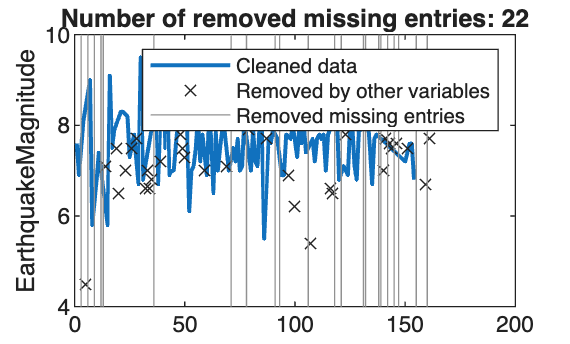

% Remove missing data
[tsunamisClean,missingIndices] = rmmissing(tsunamis, ...
    DataVariables=["EarthquakeMagnitude","IidaMagnitude"]);

% Display results
figure
% Get locations of missing data
indicesForPlot = ismissing(tsunamis.EarthquakeMagnitude);
mask = missingIndices & ~indicesForPlot;

% Plot cleaned data
plot(find(~missingIndices),tsunamisClean.EarthquakeMagnitude,SeriesIndex=1, ...
    LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot data in rows where other variables contain missing entries
plot(find(mask),tsunamis.EarthquakeMagnitude(mask),"x",SeriesIndex="none", ...
    DisplayName="Removed by other variables")

% Plot removed missing entries
x = repelem(find(indicesForPlot),3);
y = repmat([ylim(gca) missing]',nnz(indicesForPlot),1);
plot(x,y,"Color",[145 145 145]/255,DisplayName="Removed missing entries")
title("Number of removed missing entries: " + nnz(indicesForPlot))

hold off
legend
ylabel("EarthquakeMagnitude")

clear indicesForPlot mask x y

p = polyfit(tsunamisClean.EarthquakeMagnitude, tsunamisClean.IidaMagnitude, 1)

p =     0.8734   -4.9547


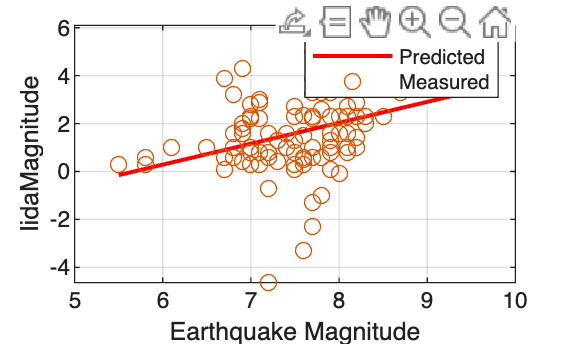

% Evaluate the polynomial fit and generate fitted values
fittedValues = polyval(p, tsunamisClean.EarthquakeMagnitude);
% Plot the fitted values against the cleaned data
plot(tsunamisClean.EarthquakeMagnitude, fittedValues, 'r-', ...
    LineWidth=1.5);
xlabel("Earthquake Magnitude");
ylabel("IidaMagnitude")
hold on
scatter(tsunamisClean.EarthquakeMagnitude, tsunamisClean.IidaMagnitude)
hold off
grid on
legend("Predicted", "Measured")

polyval(p,4)

ans = -1.4611